clear
format short
digits(3)
syms t
% Цепь на рис.1.10

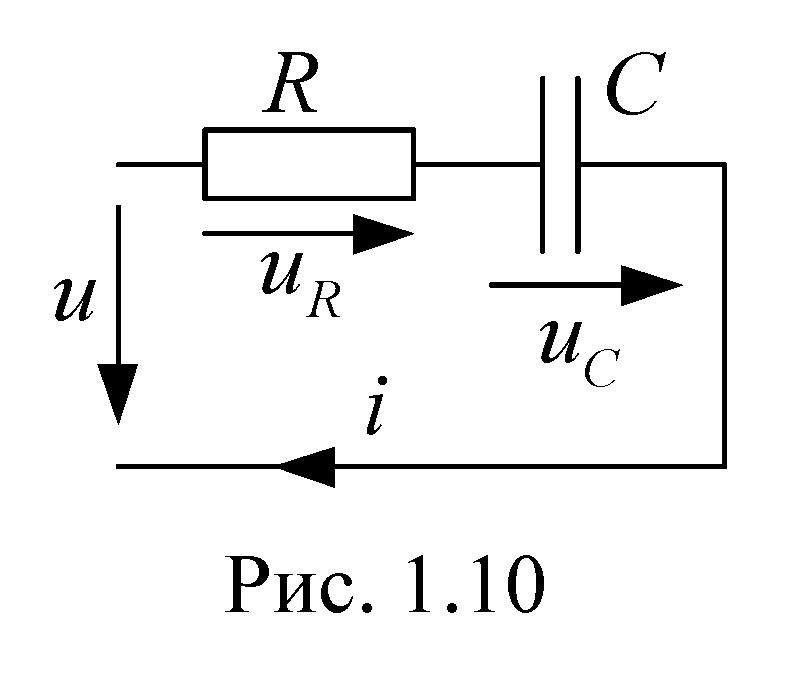

u=141*sin(314*t)

$$u = 141\,\sin\left(314\,t\right)$$

U_m=141

U_m = 141

omega=314

omega = 314

R=30 % Ом

R = 30

C=79.62 % мкФ

C = 79.6200

omega=314 % c^(-1)

omega = 314

Реактивное сопротивление емкости C 

X_C=1/(omega*C*1e-6)

X_C = 39.9989

X_C=40 % Ом

X_C = 40

Полное сопротивление цепи

Z=sqrt(R^2+X_C^2)  % Ом

Z = 50

% Амплитудные значения
I_m=round(U_m/Z,2)  % тока

I_m = 2.8200

U_mR=R*I_m  % напряжения на резисторе R

U_mR = 84.6000

U_mC=X_C*I_m   % напряжения на емкости C

U_mC = 112.8000

Угол сдвига фаз между напряжением и током

% phi=atan(X_ek/R)
phi=atan(-X_C/R)*180/pi   % град

phi = -53.1301

psi_i=vpa(-phi*pi/180)

$$psi\_i = 0.927$$

% Начальная фаза тока из соотн. psi_u-psi_i=phi => psi_i=-phi=53 град

Мгновенные значения тока и напряжений на участках цепи

i=I_m*sin(omega*t+psi_i)

$$i = \frac{141\,\sin\left(314\,t+0.927\right)}{50}$$

u_R=U_mR*sin(omega*t+psi_i)

$$u\_R = \frac{423\,\sin\left(314\,t+0.927\right)}{5}$$

u_C=U_mC*sin(omega*t+psi_i-pi/2)

$$u\_C = \frac{564\,\sin\left(314\,t-\frac{\pi }{2}+0.927\right)}{5}$$

Действующие значения:

I=round(I_m/sqrt(2)), U_R=round(U_mR/sqrt(2)), U_C=round(U_mC/sqrt(2))

I = 2

U_R = 60

U_C = 80